question 2

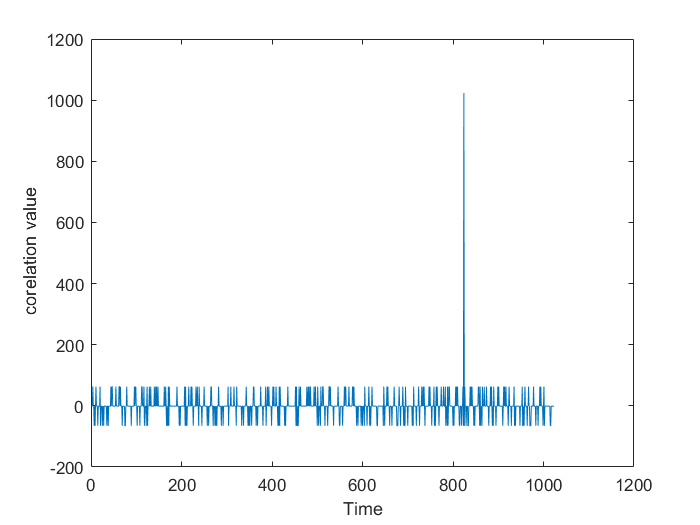

% defining parameters
f_chip = 1023000;  %chipping frequency
Sampling_frequency =f_chip*1; %sampling frequency assumed (can change it in multiples of chipping frequency)
code_length = 1023;

PRN8 = gps.code_generator(8,Sampling_frequency);  
PRN8_change_delay = gps.change(circshift(PRN8,200));
circular_arr = gps.circular_corr(PRN8_change_delay);
arr_output  = circular_arr * transpose(gps.change(PRN8));
t= linspace(1,code_length*(Sampling_frequency/f_chip),code_length*(Sampling_frequency/f_chip));
plot(t,arr_output);
ylabel(' corelation value');
xlabel('Time');

question 3

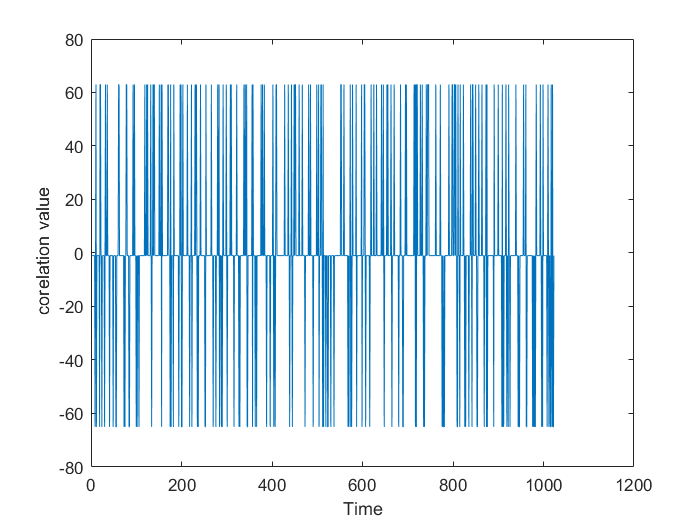

% defining parameters
f_chip = 1023000;  %chipping frequency given
Sampling_frequency =f_chip*1; 
code_length = 1023;  % given 

PRN8 = gps.code_generator(8,Sampling_frequency);
PRN16 = gps.code_generator(16,Sampling_frequency);
PRN8_change_transpose = transpose(gps.change(PRN8));
PRN16_change_delay = gps.change(circshift(PRN16,900));
circular_arr= gps.circular_corr(PRN16_change_delay);
arr_output  = circular_arr *  transpose(gps.change(PRN8));

t= linspace(1,code_length*(Sampling_frequency/f_chip),code_length*(Sampling_frequency/f_chip));

plot(t,arr_output);
ylabel(' corelation value');
xlabel('Time');

question 4

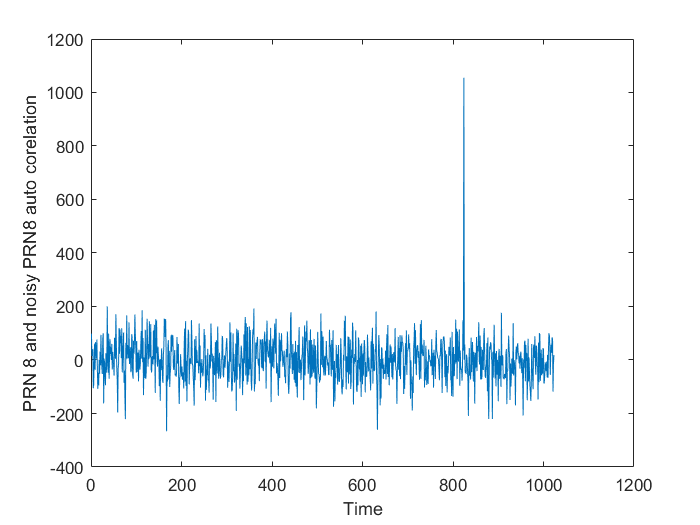

% defining parameters
f_chip = 1023000;  %chipping frequency given
Sampling_frequency =f_chip*1; 
code_length = 1023;  % given 

PRN8 = gps.code_generator(8,Sampling_frequency);
PRN8_change_delay = gps.change(circshift(PRN8,200));
variance = 4;
W = sqrt(variance).*randn(1,size(PRN8_change_delay,2)); %Gaussian white noise W
PRN8_change_delay_noise = PRN8_change_delay + W; %Add the noise
circular_arr = gps.circular_corr(PRN8_change_delay_noise);
arr_output  = circular_arr * transpose(gps.change(PRN8));

t= linspace(1,code_length*(Sampling_frequency/f_chip),code_length*(Sampling_frequency/f_chip));
plot(t,arr_output);
ylabel('PRN 8 and noisy PRN8 auto corelation');
xlabel('Time');

question 5

Parrallel phase aquisition

clear ; close all;clc;
% Loading the data file
intodat = 1000; 
fid  = fopen('.\SiGe_Bands-L1.dat', 'r');
fseek(fid,intodat, 'bof'); 
idata = fread(fid, 1*16368, 'int8');  %  reading data for 1 millisecond 


fs=16368000;   % sampling frequency given
ts= 1/fs;      %sampling time
f_chip = 1023000;  %chipping frequency
codeLength = 1023;  
Total_samples = round((fs/f_chip)*codeLength); %samples for full time
CA_Code_Table = gps.CaTable(fs);


f_IF = 4092000;  %Intermediate frequency
f_step = 500;   %frequency step
f_doppler = 10000; %frequecy shift due to doppler for moving satellite

f_bins = ((2*f_doppler/f_step) + 1) ; % number of frequency bins
fc = ones (f_bins);   % initializing carrier frequency
results = ones(f_bins,16368); % initializing final results
threshold = 2.2 *10^6;   % threshold value for peak decided by analyzing peak for all PRN numbers
k=1;  % counter for storing prn numbers for all satellite

for i = 1:f_bins
    fc(i) = (f_IF - f_doppler) + f_step*(i-1);
end

[Xp,Yp] = meshgrid(1:Total_samples,fc(1:f_bins));


for PRN_number = 1:32
    CFFT = transpose(conj(fft(CA_Code_Table(PRN_number,:))));
    for i = 1:f_bins
    local_oscillation_I = transpose(cos(2*pi* fc(i)* ts*(0:Total_samples-1)));  % inphase 
    local_oscillation_Q = transpose(sin(2*pi* fc(i)* ts*(0:Total_samples-1)));  % quadrature 
     I = local_oscillation_I.*idata;
     Q = local_oscillation_Q.*idata;
     
     Y = I + j*Q;
     Yfft = fft(Y);
     Z =  Yfft.* CFFT;
     Zifft  = ifft(Z);
     output = abs(Zifft).^2;
     results(i,:) = output;
    end
    
    % uncomment this section to obtain 3d plots for each PRN number

%         figure(PRN_number);
%         surf(Xp,Yp,results);
%         title (['PRN Number = ',num2str(PRN_number)] );
%         xlabel("Sampling Number");
%         ylabel("Frequency");

     
     max_value(1,PRN_number)= max(results,[],'all');
    [peak,freqBinIndex] = max(max(results,[],2));
    [peak,codPhase] = max(max(results));
    
    if (peak > threshold)
        if k==1
            fprintf('PRN  | frequency | codephase | peak value\n')
        end
        fprintf('%2d   | %8d  | %6d    | %5d\n',PRN_number,((f_IF - f_doppler) + f_step*freqBinIndex), codPhase, peak)
        visible_sat(1,k) = PRN_number;
        k = k+1;
    end
    
end

PRN  | frequency | codephase | peak value


 1   |  4090000  |   6698    | 3.229492e+06
 8   |  4088500  |    932    | 2.858113e+06
 9   |  4091000  |   4972    | 3.704379e+06
11   |  4089500  |  14021    | 2.234174e+06
17   |  4094000  |  11027    | 3.366964e+06
28   |  4093000  |   5144    | 3.166421e+06
